# Mapping

## Things to know

Use the idea behind the line tracing

Visit: [https://es.wikipedia.org/wiki/Algoritmo_de_Bresenham](https://es.wikipedia.org/wiki/Algoritmo_de_Bresenham)

and download an efficient function at: [https://es.mathworks.com/matlabcentral/fileexchange/28190-bresenham-optimized-for-matlab](https://es.mathworks.com/matlabcentral/fileexchange/28190-bresenham-optimized-for-matlab)

## Creating a map

Define your map resolution. I recomend $10{\textrm{cm}}^2$ resolution for the short project.

For example a $1{\textrm{cm}}^2$ resolution of a map of 1 $1\textrm{x1}m^2$

Map=ones(100,100)*0.5 % 0.5 for grey color unexplored

Map =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000   

## Showing results

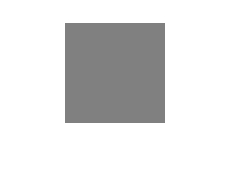

imshow (Map)

## Ocuppancy grid

Use bresenham for ray tracing for detecting free space / wall / unexplored enviroment.

Example: the robot is at position [0.2 0,3]  and at some scaning angle it detect a wall in [0.9 0.75]

[x y]=bresenham(0.2*100,0.3*100,0.9*100,0.75*100)

dx = 70

dy = 45

steep = logical
   0


q =      0
     1
     0
     1
     1
     0
     1
     0
     1
     1


x =     20
    21
    22
    23
    24
    25
    26
    27
    28
    29


y =     30
    31
    31
    32
    33
    33
    34
    34
    35
    36


## Displaying the results

Free space and wall

L=length(x);
    for i=1:L
        Map(x(i),y(i))=1;
    end
Map(0.9*100,0.75*100)=0   

Map =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

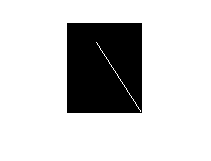

imshow (Map)  